# A system described by a linear constant coefficient differential equation:


$$\left\lbrace \begin{array}{cc}
y^{\prime \prime \left(t\right)} +3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right) & f\left(t\right)=e^{-t} u\left(t\right)\\
y\left(0_- \right)=1 & y^{\prime } \left(0_- \right)=2
\end{array}\right.$$


## zero input response: yzi


$$\left\lbrace \begin{array}{cc}
y^{\prime \prime \left(t\right)} +3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right) & f\left(t\right)=0\\
y\left(0_- \right)=1 & y^{\prime } \left(0_- \right)=2
\end{array}\right.$$


## zero state response: yzs


$$\left\lbrace \begin{array}{cc}
y^{\prime \prime \left(t\right)} +3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right) & f\left(t\right)=e^{-t} u\left(t\right)\\
y\left(0_- \right)=0;y^{\prime } \left(0_- \right)=0 & y\left(0_+ \right)=?;\;y^{\prime } \left(0_+ \right)=?
\end{array}\right.$$


## full response: yfull


$$y_{\textrm{ful}} =y_{\textrm{zi}} +y_{\textrm{zs}}$$


## **Zero-Input Response（Symbolic method****）**


$$y^{\textrm{''}} \left(t\right)+3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right),\;f\left(t\right)=e^{-t} u\left(t\right),\;y\left(0_- \right)=1,y^, \left(0_- \right)=2$$
 

Find the zero_input response:

- Represent differentiation by using the **diff** function

- Specify a differential equation by using ==

- use simplify to  **simplify** the uncertainty model

clear
syms y(t) 
D2y = diff(y,t,2); 
Dy = diff(y,t); 
eqn = D2y+3*Dy+2*y==0; 
conds = [y(0)==1, Dy(0)==2]; 
ysol = dsolve(eqn, conds)

$$ysol = {\mathrm{e}}^{-2\,t}\,\left(4\,{\mathrm{e}}^{t}-3\right)$$

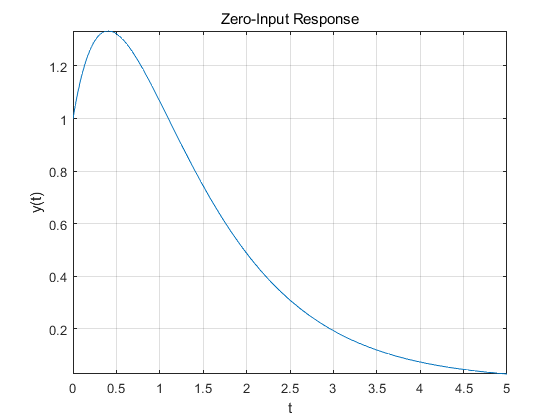

fplot(ysol,[0 5]);xlabel('t');ylabel('y(t)');title('Zero-Input Response'),grid on;

## **Zero-State Response ****（****Symbolic method****）**


$$y^{\textrm{''}} \left(t\right)+3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right),\;f\left(t\right)=e^{-t} u\left(t\right),\;y\left(0_- \right)=1,y^, \left(0_- \right)=2$$
  

Find the zero_state response:

- Represent differentiation by using the **diff** function

- Specify a differential equation by using ==

- $y\left(0_- \right)=0,\;y^, \left(0_- \right)=0$,  so $y\left(0_+ \right)=0,\;y^, \left(0_+ \right)=0$

clear
syms y(t) 
D2y = diff(y,t,2); 
Dy = diff(y,t); 
eqn = D2y+3*Dy+2*y==exp(-t)*heaviside(t); 
conds = [y(0)==0, Dy(0)==0];   % sometimes you need to use 0.001 instead of 0+
yzs = dsolve(eqn, conds)

$$yzs = \frac{{\mathrm{e}}^{-2\,t}}{2}+{\mathrm{e}}^{-2\,t}\,\left(\frac{\mathrm{sign}\left(t\right)}{2}-\frac{{\mathrm{e}}^{t}\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}\right)+\frac{t\,{\mathrm{e}}^{-t}\,\left(\mathrm{sign}\left(t\right)+1\right)}{2}$$

simplify(yzs)

$$ans = \frac{{\mathrm{e}}^{-2\,t}\,\left(\mathrm{sign}\left(t\right)+1\right)\,\left(t\,{\mathrm{e}}^{t}-{\mathrm{e}}^{t}+1\right)}{2}$$

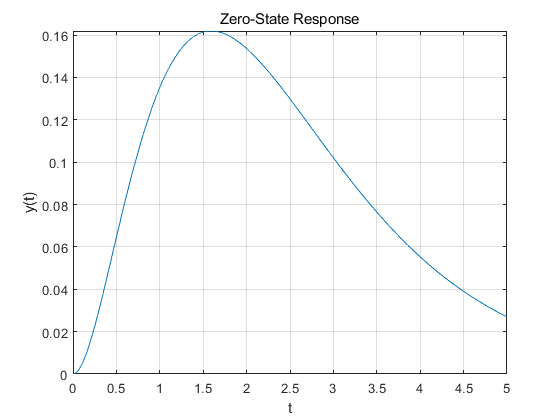

fplot(yzs,[0 5]);xlabel('t');ylabel('y(t)');title('Zero-State Response'),grid on;

it is the same as the result : $y_{\textrm{st}} =\left(e^{-2t} -{\mathrm{e}}^{-t} +te^{-t} \right)u\left(t\right)$

### Some tips

$y^{\mathrm{''}} \left(t\right)+2y^{\prime } \left(t\right)+3y\left(t\right)=f^{\prime } \left(t\right)+2f\left(t\right),f\left(t\right)=5\mathrm{sin2}\pi t$, find the zero-state response

- When there are multiple equations, enclose them in parentheses, just like multiple conditions

- When there are multiple equations, you will get multiple results, use dot to refer to the results you need.

clear; clf;
syms y(t1) f(t1)
D2y = diff(y,t1,2); 
Dy = diff(y,t1); 
Df = diff(f,t1);
eqn1 = D2y+2*Dy+3*y==Df+2*f; 
eqn2 = f==5*sin(2*pi*t1);
eqns = [eqn1 eqn2];
conds = [y(0)==0, Dy(0)==0];    % the right side of the equation is continuous, so the condition has no jump 
ysol = dsolve(eqns, conds)

ysol = 包含以下字段的 struct :
    f: [1×1 sym]
    y: [1×1 sym]


yzs = simplify(ysol.y);  % when have several eqn, the result will have several output. pick the one you need

$$yzs = \begin{array}{l} \frac{{\mathrm{e}}^{-t_{1}}\,\left(10\,\pi \,\sigma_{2}+40\,\pi^{3}\,\sigma_{2}+30\,{\mathrm{e}}^{t_{1}}\,\sin\left(2\,\pi \,t_{1}\right)-10\,\pi \,{\mathrm{e}}^{t_{1}}\,\sigma_{3}+20\,\sqrt{2}\,\pi^{3}\,\sigma_{1}-40\,\pi^{3}\,{\mathrm{e}}^{t_{1}}\,\sigma_{3}-25\,\pi \,\sqrt{2}\,\sigma_{1}\right)}{16\,\pi^{4}-8\,\pi^{2}+9}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\sqrt{2}\,t_{1}\right)\\ \sigma_{2}=\cos\left(\sqrt{2}\,t_{1}\right)\\ \sigma_{3}=\cos\left(2\,\pi \,t_{1}\right) \end{array}$$

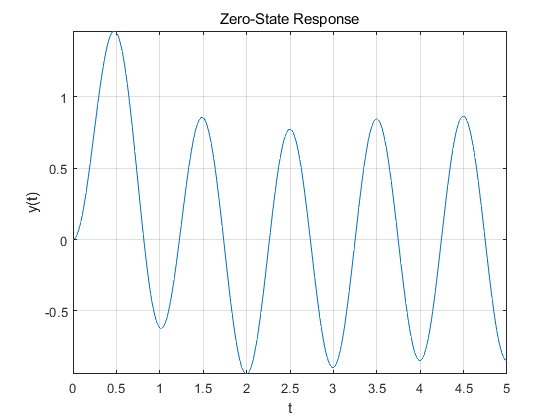

fplot(yzs,[0 5]);xlabel('t');ylabel('y(t)');title('Zero-State Response'),grid on;

## **Zero-State Response （****Numerical method****）**


$$\left\lbrace \begin{array}{cc}
y^{\prime \prime \left(t\right)} +3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right) & f\left(t\right)=e^{-t} u\left(t\right)\\
y\left(0_- \right)=0;y^{\prime } \left(0_- \right)=0 & y\left(0_+ \right)=?;\;y^{\prime } \left(0_+ \right)=?
\end{array}\right.$$


- When trying to find out the zero-state response, we need to know the state of 0+. 

- As we have already mentioned, 0+ comes from 0- and the differential equation. 

- In face, for zero-state response, 0- is always 0. 

- Therefore, 0+ is actually only related to the differential equation which describes the system. 

- So  it can be considered that 0+ state only depends on the characteristics of the system. 

- Thus the zero-state response depends on the  characteristics of the system and the input signal.

 In MATLAB,** lsim** is the function to find out the zero-state response in this way.


$$y=\textrm{lsim}\left(\textrm{sys},f,t\right)$$



$$\textrm{sys}=\textrm{tf}\left(b,a\right)$$



$$\begin{array}{l}
a_3 y^{\prime \prime \prime } \left(t\right)+a_2 y^{\prime \prime } \left(t\right)+a_1 y^{\prime } \left(t\right)+a_0 y\left(t\right)=b_3 f^{\prime \prime \prime } \left(t\right)+b_2 f^{\prime \prime } \left(t\right)+b_1 f^{\prime } \left(t\right)+b_0 f\left(t\right)\\
a=\left\lbrack a_3 ,a_2 ,a_1 ,a_0 \right\rbrack \\
b=\left\lbrack b_3 ,b_2 ,b_1 ,b_0 \right\rbrack 
\end{array}$$


Note: if the Nth derivative is missing in the differential equation, the corresponding element in the vector should be set to zero.

$y^{\textrm{''}} \left(t\right)+2y\left(t\right)=f\left(t\right),\;f\left(t\right)=e^{-t} u\left(t\right),\;y\left(0_- \right)=1,y^, \left(0_- \right)=2$, find the zero-state response

clear;clf;
t = 0:0.01:5;
sys = tf(1,[1 0 2])%transfer function

sys =
 
     1
  -------
  s^2 + 2
 
Continuous-time transfer function.



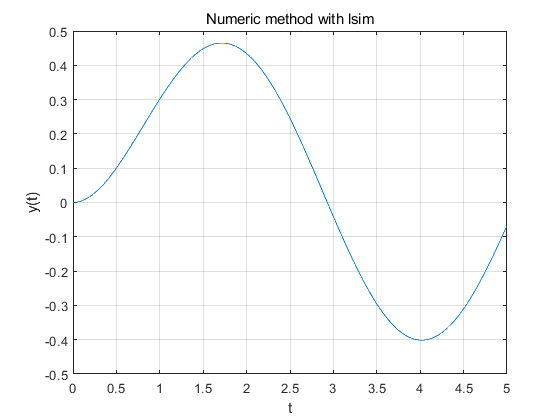

f = exp(-t).*heaviside(t);
y=lsim(sys,f,t);
plot(t,y);xlabel('t');ylabel('y(t)');title('Numeric method with lsim'),grid on;

### **Subs**

$y^{\textrm{''}} \left(t\right)+3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right),\;f\left(t\right)=e^{-t} u\left(t\right),\;y\left(0_- \right)=1,y^, \left(0_- \right)=2$, find the zero-state response

clear
t = 0:0.01:5;

syms y(t1) 
D2y = diff(y,t1,2); 
Dy = diff(y,t1); 
eqn = D2y+3*Dy+2*y==exp(-t1); 
conds = [y(0)==0, Dy(0)==0];
ysol = dsolve(eqn, conds);%符号形式

yzs = subs(ysol,'t1',t)

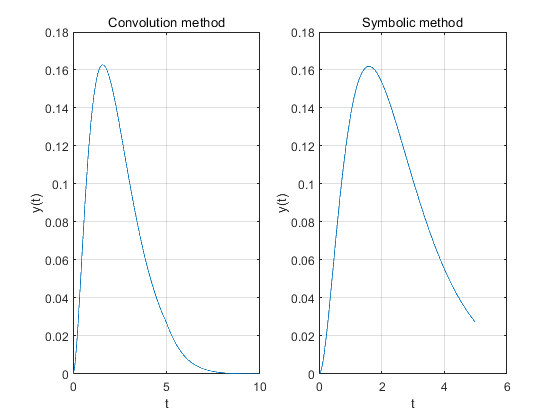

plot(t,yzs);xlabel('t');ylabel('y(t)');title('Symbolic method'),grid on;

## Convolution with Impulse Response (Numerical Method)

We can also find out zero-state response by convolving the impulse response and the input signal.


$$\begin{array}{l}
h=\textrm{impulse}\left(\textrm{sys},t\right)\;\textrm{or}\;\left\lbrack h\;\;t\right\rbrack =\textrm{impulse}\left(\textrm{sys}\right)\\
g=\textrm{step}\left(\textrm{sys},t\right)\;\textrm{or}\;\left\lbrack g\;t\right\rbrack =\textrm{step}\left(\textrm{sys}\right)
\end{array}$$


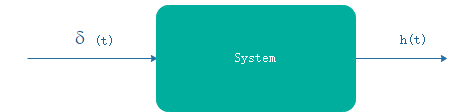

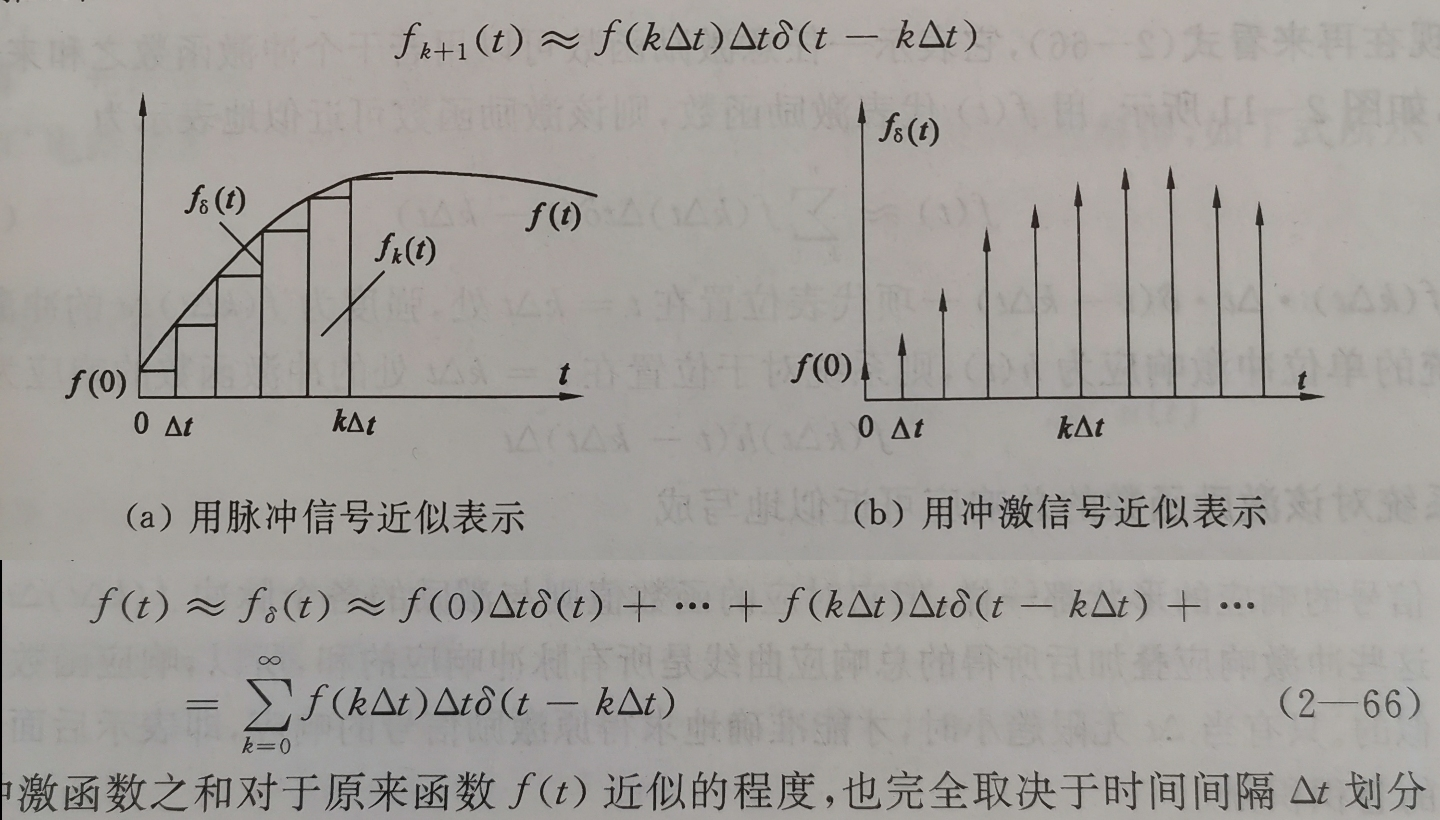

 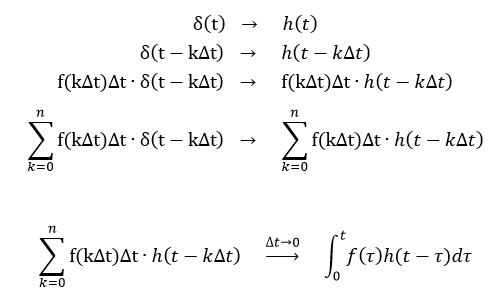


$$y^{\textrm{''}} \left(t\right)+3y^{\prime } \left(t\right)+2y\left(t\right)=f\left(t\right),\;f\left(t\right)=e^{-t} u\left(t\right),\;y\left(0_- \right)=1,y^, \left(0_- \right)=2$$
 

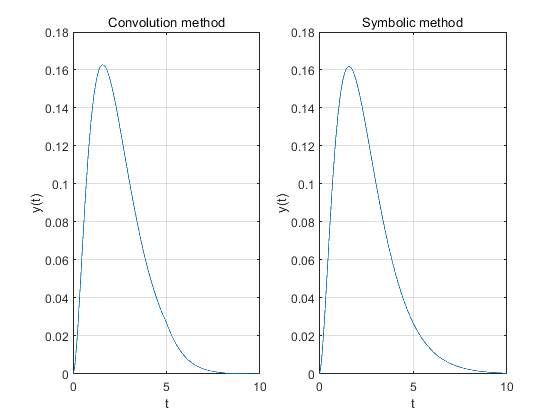

clear;clf;
dt = 0.01;
t = 0:dt:5;

sys = tf(1,[1,3,2]);
h = impulse(sys,t);
f = exp(-t);
y = conv(h,f)*dt;   % for continuous method, a dt is required
n = length(y);
tt = (0:n-1)*dt;%卷积后长度改变
subplot(1,2,1);plot(tt,y);xlabel('t');ylabel('y(t)');title('Convolution method'),grid on;

syms y(t1) 
D2y = diff(y,t1,2); 
Dy = diff(y,t1); 
eqn = D2y+3*Dy+2*y==exp(-t1); 
conds = [y(0)==0, Dy(0)==0];
ysol = dsolve(eqn, conds); 
yzs = subs(ysol,'t1',tt);
subplot(1,2,2);plot(tt,yzs);xlabel('t');ylabel('y(t)');title('Symbolic method'),grid on;

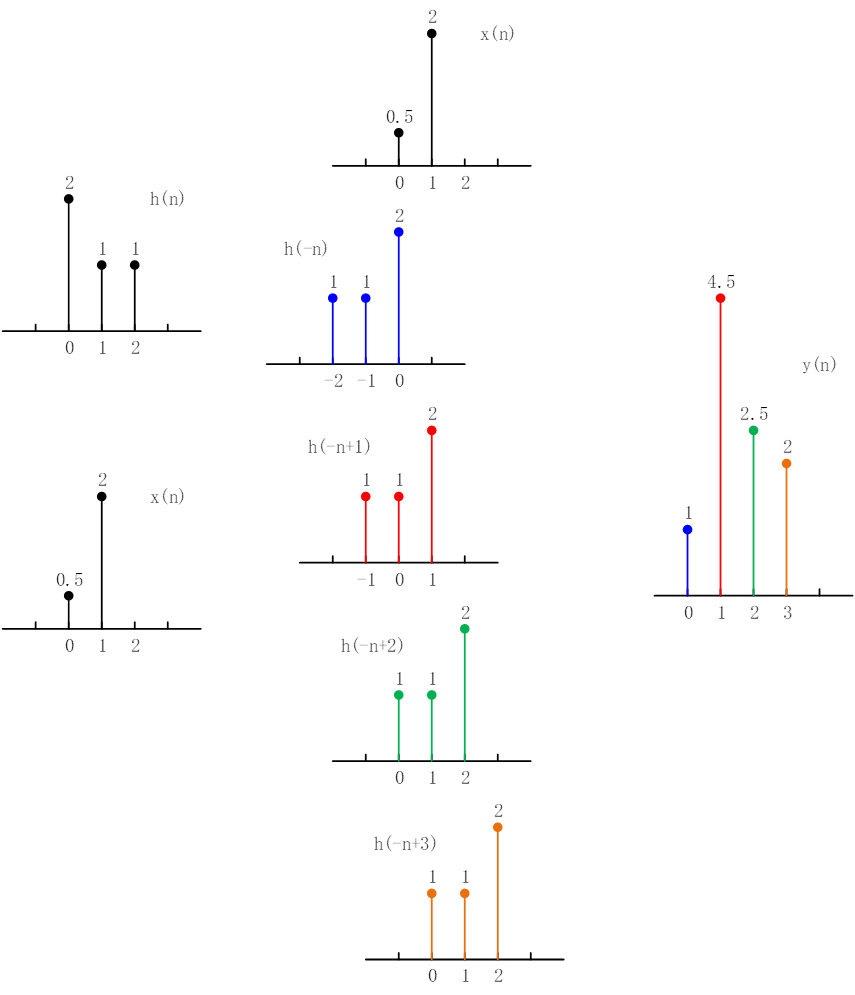

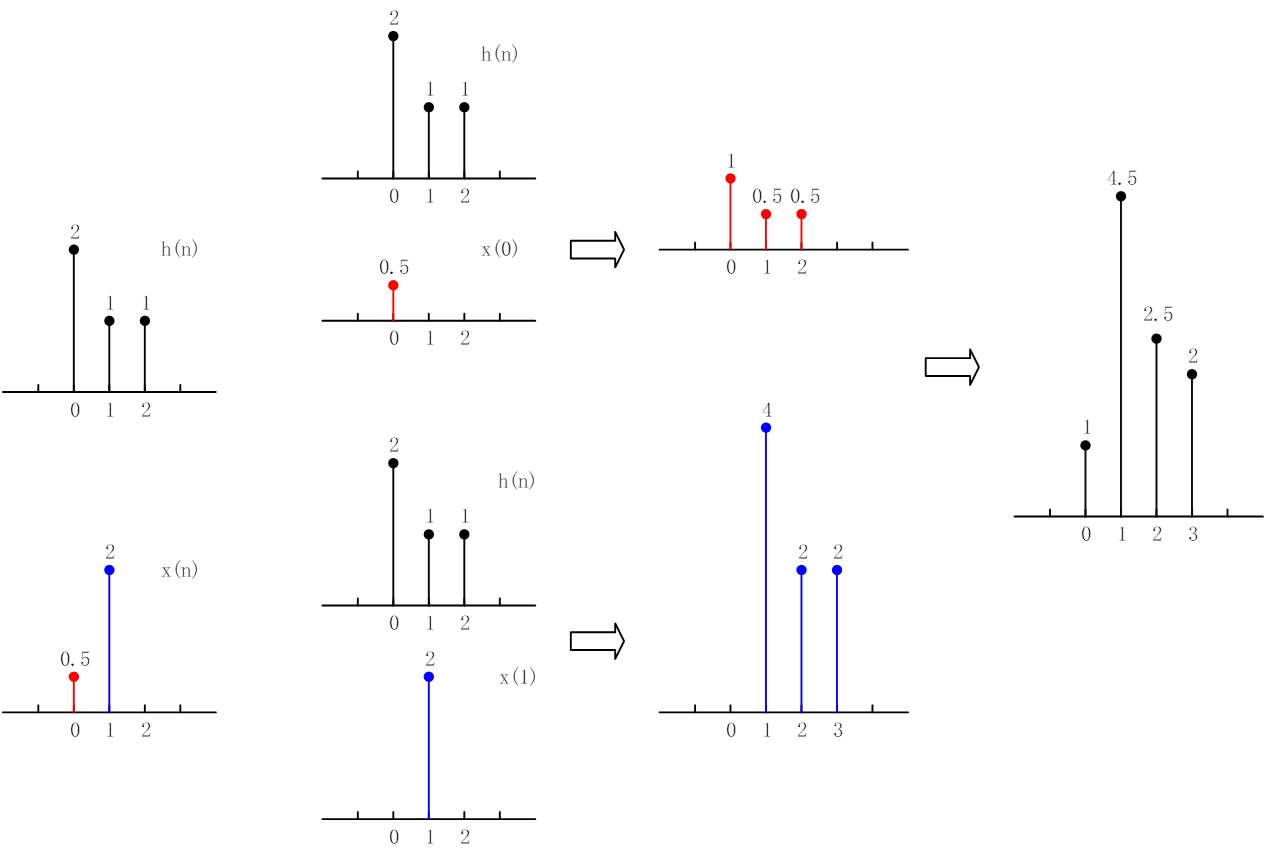

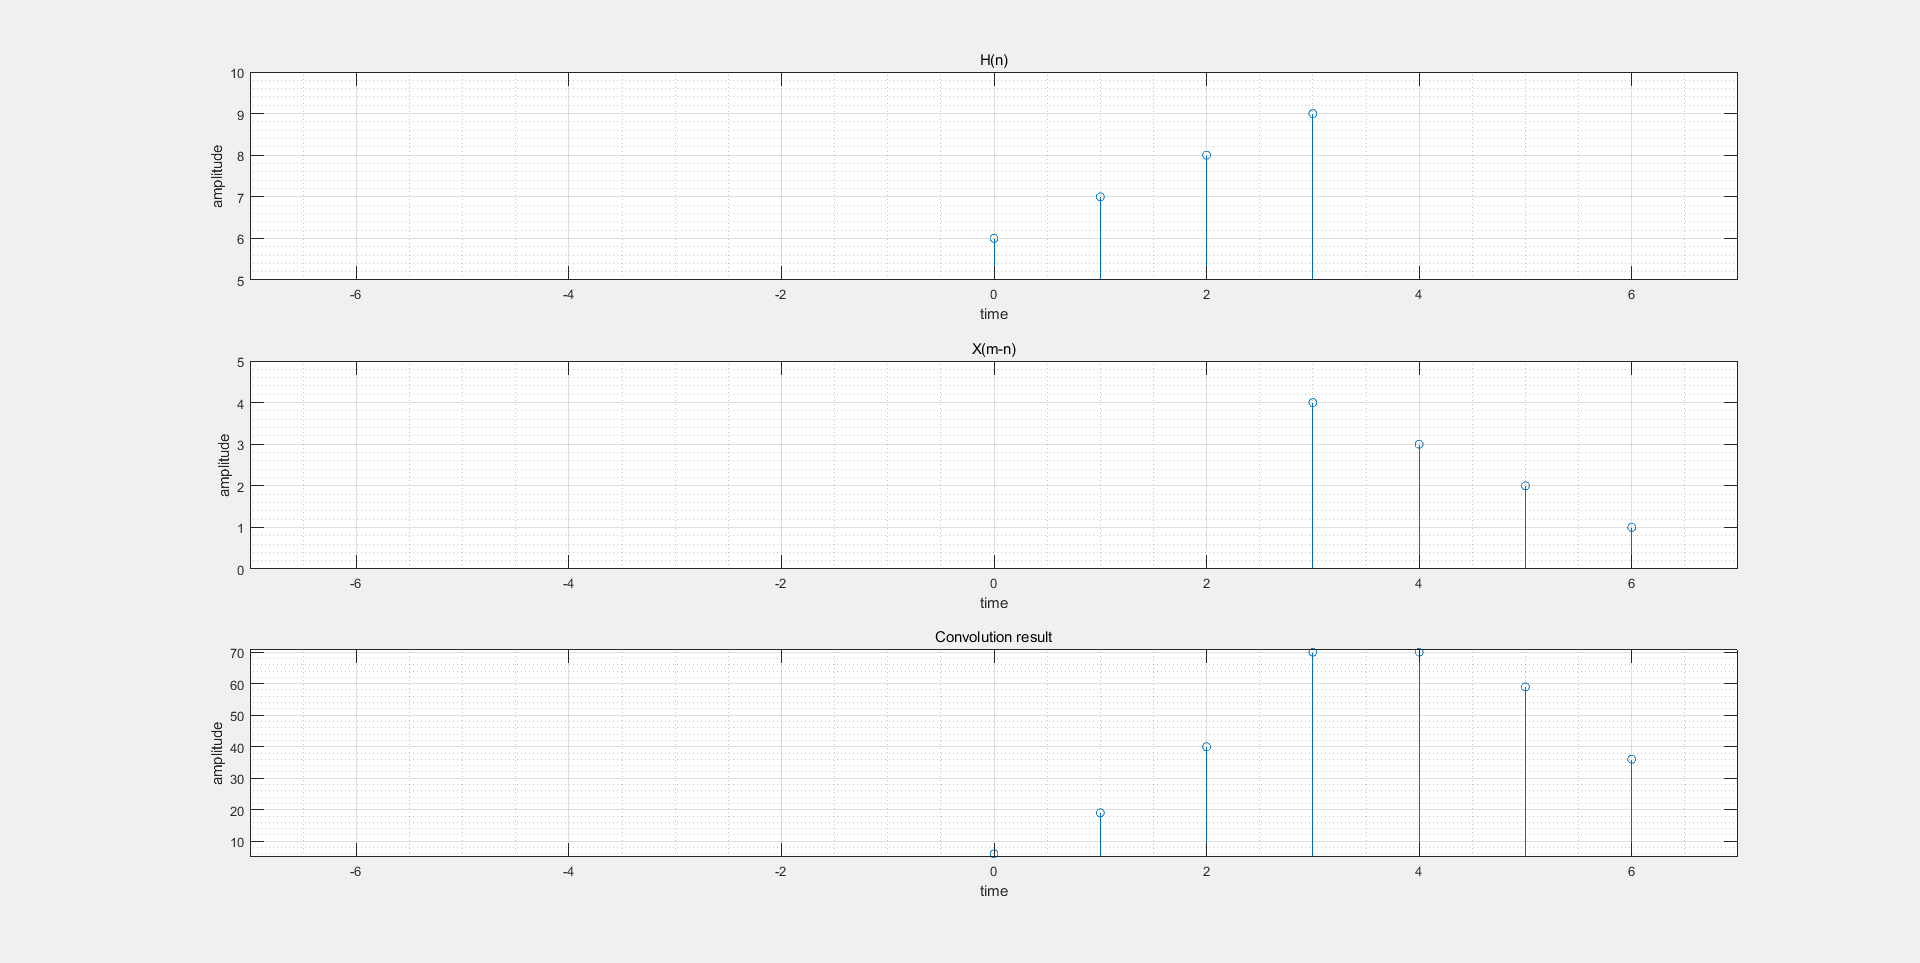

clear;clf;
x = [1 2 3 4];
h = [6 7 8 9];
Lab2_convolution(x,h);

% Lab2_convolution2(a,b);
